clear all, clc, close all;

fid = fopen('../FPD/data/policy.json');
raw = fread(fid); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

aTc = val.v1;
IPTG = val.v2;

sbioloadproject Genetic_Toggle_Switch_Simplified.sbproj

for i = 1:length(IPTG)
    trigger = strcat('time >= ', int2str((i-1)));
    evnt_IPTG = strcat('IPTG = ', num2str(IPTG(i)), '*u0');
    evnt_aTc = strcat('aTc = ', num2str(aTc(i)), '*u0');
    addevent(m1, trigger, {evnt_aTc, evnt_IPTG});
end

sim = sbiosimulate(m1);

avg_time = (0:1:1200)

avg_time =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


LacI = sim.Data(:,2);
TetR = sim.Data(:,3);

[avg_LacI, avg_TetR] = compute_average_trajectory(LacI, TetR, avg_time)

avg_LacI =    26.3720   26.4194   26.4665   26.5133   26.5598   26.6062   26.6522   26.6980   26.7435   26.7888   26.8338   26.8786   26.9231   26.9674   27.0114   27.0552   27.0987   27.1419   27.1849   27.2277   27.2702   27.3124   27.3544   27.3962   27.4377   27.4790   27.5200   27.5608   27.6013   27.6416   27.6817   27.7215   27.7611   27.8004   27.8395   27.8783   27.9169   27.9553   27.9934   28.0313   28.0690   28.1064   28.1436   28.1806   28.2173   28.2538   28.2901   28.3261   28.3619   28.3975


avg_TetR =    13.4602   13.4545   13.4487   13.4430   13.4374   13.4318   13.4262   13.4207   13.4153   13.4099   13.4045   13.3992   13.3939   13.3886   13.3834   13.3783   13.3732   13.3681   13.3631   13.3581   13.3532   13.3483   13.3434   13.3386   13.3339   13.3291   13.3245   13.3198   13.3152   13.3107   13.3062   13.3017   13.2973   13.2929   13.2885   13.2842   13.2800   13.2757   13.2716   13.2674   13.2633   13.2592   13.2552   13.2512   13.2473   13.2434   13.2395   13.2357   13.2319   13.2282


LacI_ref = 23.48;
TetR_ref = 10.00;

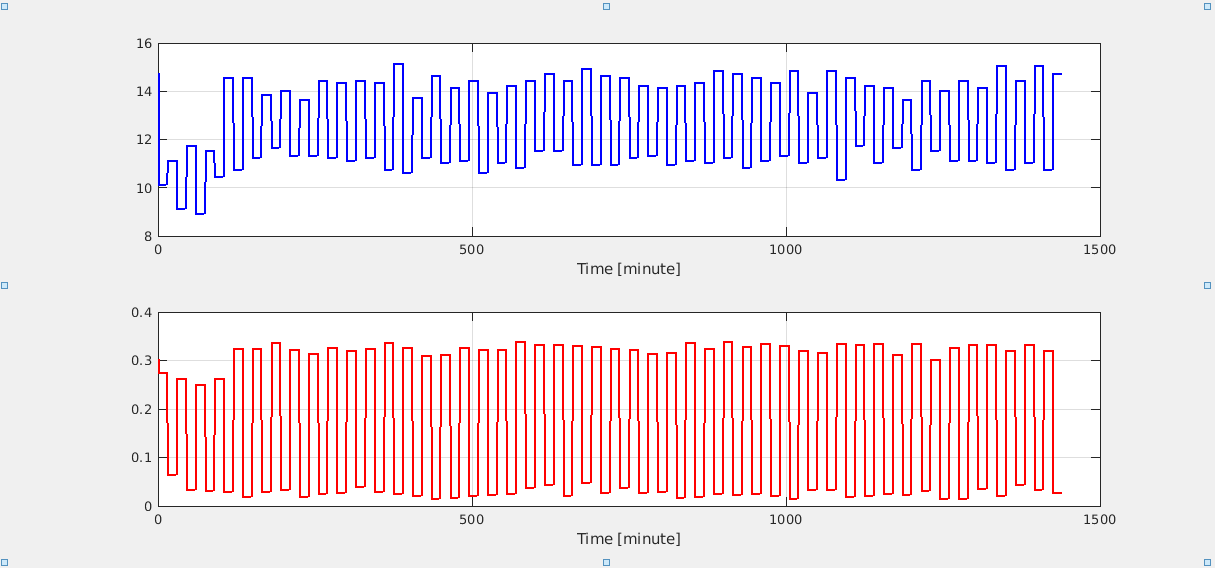

close all;
figure(1);
clf reset
plotbrowser('on');
title('Inputs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,4), 'DisplayName','aTc');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,1), 'DisplayName','IPTG');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

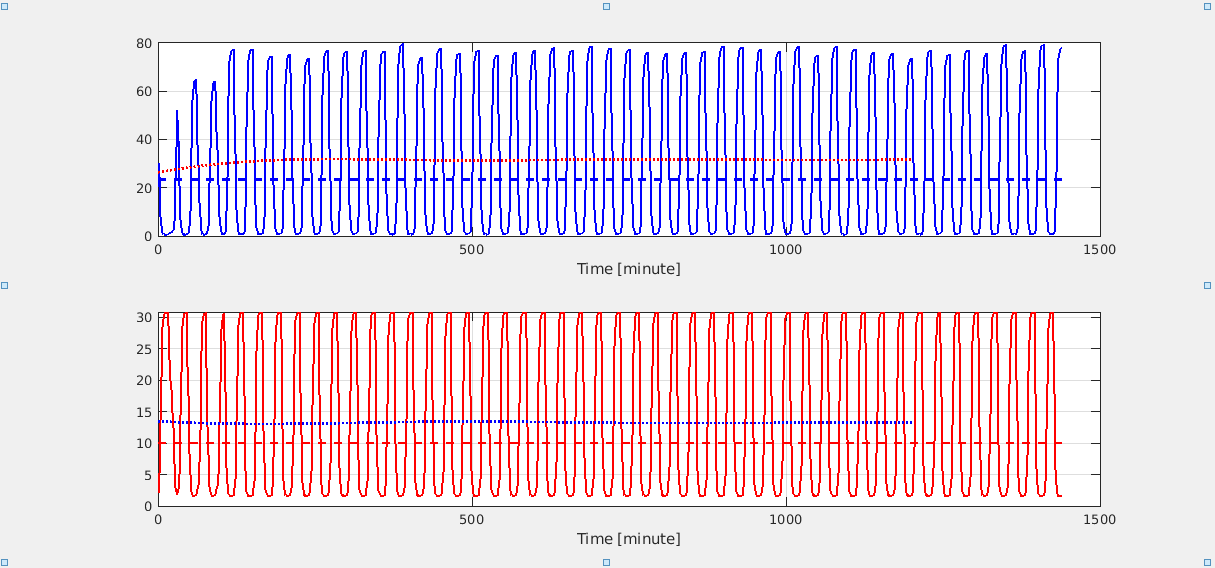

figure(2);
clf reset
plotbrowser('on');
title('Proteins');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,2), 'DisplayName','LacI');
set(pl,'linewidth',2, 'Color', 'b');
hold on
pl = plot(sim.Time, LacI_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', '--');
pl = plot(avg_time, avg_LacI, 'DisplayName','Average LacI');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,3), 'DisplayName','TetR');
set(pl,'linewidth',2, 'Color', 'r');
hold on
pl = plot(sim.Time, TetR_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', '--');
pl = plot(avg_time, avg_TetR, 'DisplayName','Average TetR');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

[ISE,ITAE] = compute_performance_metrics(avg_LacI, avg_TetR, LacI_ref, TetR_ref)

ISE = 258.3115

ITAE = 3.4029e+05